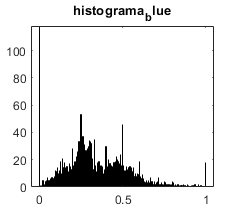

length_blue = zeros(1,30);
length_red = zeros(1,30);
for i = 1:1
    if i < 10
        im = imread(strcat('0', int2str(i) ,'.jpg'));
    else
        im = imread(strcat( int2str(i) ,'.jpg'));
    end
    imshow(im)
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    I = double(r)+double(g)+double(b);
    rn = double(r)./I;
    gn = double(g)./I;
    bn = double(b)./I;
    rgbNormalizada = cat(3,rn,gn,bn);
    imshow(rgbNormalizada), title('normalitzacio naive')
    aux = 0:0.001:1;
    %aux = 0:256
    histogram(rgbNormalizada(:,:,1),aux), title('histograma_red');
    histogram(rgbNormalizada(:,:,3),aux), title('histograma_blue');
    length_red(i) =  length(rn(rn>0.7));
    length_blue(i)= length(bn(bn>0.7));
end


max(length_blue)

ans = 175

max(length_red)

ans = 1122